[filepath,name,ext] = fileparts(which('fmc_demo'));
filepath_model = strjoin({filepath,'fmc.inp'},'\');
mdl = swmm(filepath_model);

% all model components are contained in mdl.p
disp(mdl.p.subcatchments) % display the subcatchment data
figure('Name','model_layout')

       Name        RainGage        Outlet         Area     PercentImperv    Width     PercentSlope    CurbLen     Snowpack 
    __________    __________    _____________    ______    _____________    ______    ____________    _______    __________

    {'S101'  }    {'S101'  }    {'J71.72631'}     29.66       10.304        380.26       0.012           0       {0×0 char}
    {'S102'  }    {'S102'  }    {'J895.8482'}    124.61       14.392        1832.5       0.018           0       {0×0 char}
    {'S103'  }    {'S103'  }    {'J1060.963'}     51.96       13.776        731.83       0.016           0       {0×0 char}
    {'S104'  }    {'S104'  }    {'J2173.272'}      39.8       15.232     

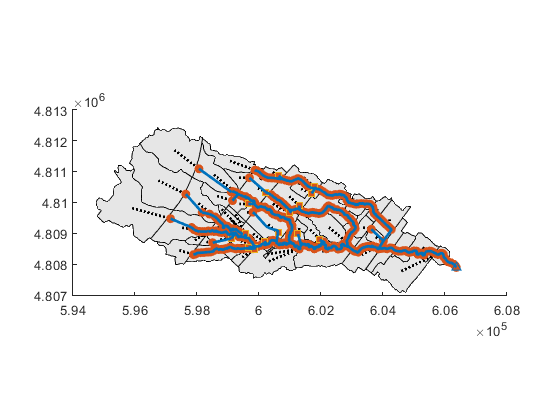

mdl = mdl.draw; % plot the model shapes

- Set the **report_start_date** (based on the evnet), **start_date** (7 days before the reporting date), and **end_date**

- Use** .runsim **to execute the simulation

- Use **.results_tt** to read the timeseries results

- Plot the modelled and observed timeseries using **plot_tt()**

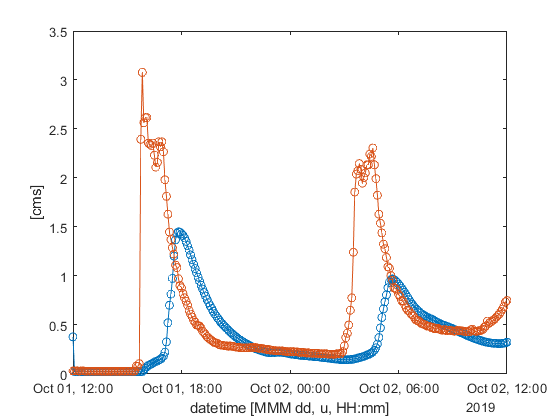

mdl.p.options.REPORT_START_DATE = datetime('2019-10-01 12:00:00','InputFormat','yyyy-MM-dd HH:mm:ss'); % specify date using datetime value
mdl.p.options.START_DATE = mdl.p.options.REPORT_START_DATE - days(7); % start 7 days before reporting
mdl.p.options.END_DATE = mdl.p.options.REPORT_START_DATE + hours(24); % end date 36 hours after start date
mdl.write_inp; % write the changes to the INP file

% run the model and save report to a specified location
dir_report = [cd,'\02_swmm_calibration\models\temp\output.rpt'];
mdl.runsim(dir_report);

tt_mod = mdl.results_tt('CJ1902.476'); % read the conduit timeseries results from the RPT file
tt_mod = tt_mod(:,'flow');
figure('Name','outflow_hydrograph');
plot_tt(tt_mod(:,'flow'),'o-','DisplayName','modelled flow'); % plot the modelled flow

load('02_swmm_calibration\models\fourteenmile\data\flow_obs_jan18-jan20.mat'); % load the observed flow data
tt_tgt = retime(tt_flow_obs,tt_mod.Properties.RowTimes,'mean'); % synchronize the observed timeseries with the modelled output
hold on

plot_tt(tt_tgt(:,'flow'),'o-','DisplayName','observed flow'); % plot the observed flow
legend('location','northeast');

fun_nse = @(x_obs,x_mod) 1 - sum((x_obs - x_mod).^2) / sum((x_obs - mean(x_obs)).^2); % anonymous function for NSE

ans = -0.2893

fun_nse(tt_tgt.Variables,tt_mod.Variables) % calculate the nash-sutcliffe efficiency
